### Testing shape generation

length_x = 5;
length_y = 1;
posn_square = [1; 3];
theta = pi/6; % Rads
resolution = 64; % Total points (distributed evenly)
points_square = generate_square(length_x, length_y, posn_square, theta, resolution);

radius = 2;
posn_circle = [-1; -3];

points_circle = generate_circle(radius, posn_circle, resolution);

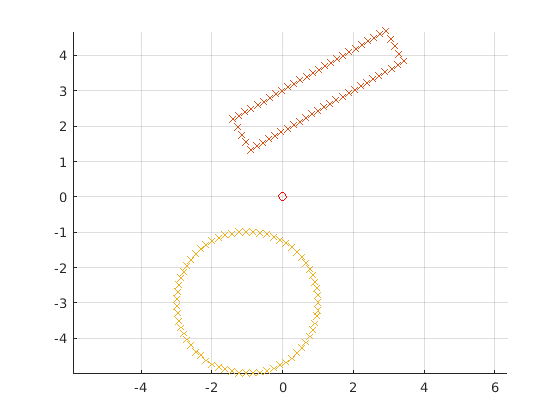

figure();
hold on

plot(0, 0, 'ro')

scatter(points_square(1, :), points_square(2, :), 'x')
scatter(points_circle(1, :), points_circle(2, :), 'x')

grid on
axis equal

### Constructing the gauntlet

function points_out = generate_square(length_x, length_y, position, theta, resolution)

% Create square points
res_x = 0.5 * resolution * length_x / (length_x + length_y);
res_y = 0.5 * resolution * length_y / (length_x + length_y);

edge_coords_x = length_x * linspace(-0.5, 0.5, res_x);
edge_coords_y = length_y * linspace(-0.5, 0.5, res_y);
const_coords_x = length_x * 0.5*ones(size(edge_coords_y));
const_coords_y = length_y * 0.5*ones(size(edge_coords_x));


top_edge = [edge_coords_x; const_coords_y];
bottom_edge = [edge_coords_x; -const_coords_y];

left_edge = [-const_coords_x; edge_coords_y];
right_edge = [const_coords_x; edge_coords_y];

points_out = [top_edge, bottom_edge, left_edge, right_edge];

% Rotate square about center
rot_mat = [cos(theta) -sin(theta);
           sin(theta)  cos(theta)];

points_out = rot_mat*points_out;

% Translate square
points_out = [points_out; ones(1, size(points_out, 2))];
trans_mat = eye(3);
trans_mat(1:2, 3) = position;

points_out = trans_mat*points_out;

end

function points_out = generate_circle(radius, position, resolution)

thetas = linspace(0, 2*pi, resolution);

% Create circle points
points_out = [radius*cos(thetas);
          radius*sin(thetas);
          ones(size(thetas))];

% Translate circle
trans_mat = eye(3);
trans_mat(1:2, 3) = position;

points_out = trans_mat*points_out;

end
